see: http://speechresearch.fiw-web.net/73.html#y6a12906

clear all
[wav, Fs] = audioread('a.wav');

有声音部分（今回は中央）を切り出す

center = fix(length(wav) / 2);   %中心のサンプル番号
cuttime = 0.04;                  %切り出す長さ[s]
wavdata = wav(center-fix(cuttime/2*Fs) : center+fix(cuttime/2*Fs));

Hamming-windowing as a pre-processing

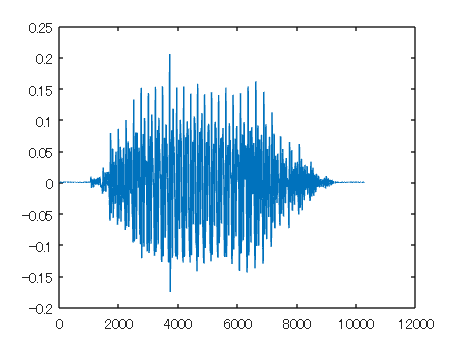

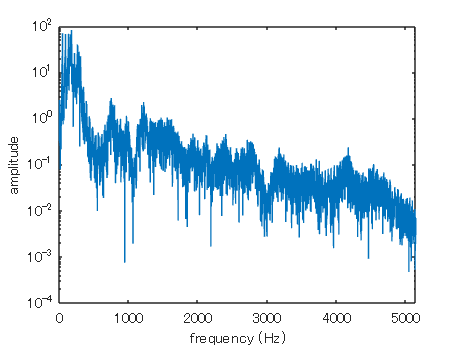

wav_windowed = hamming(length(wav)) .* wav;
plot(wav_windowed)

Formant analysis using Linear Prediction Coefficients (:LPC) 

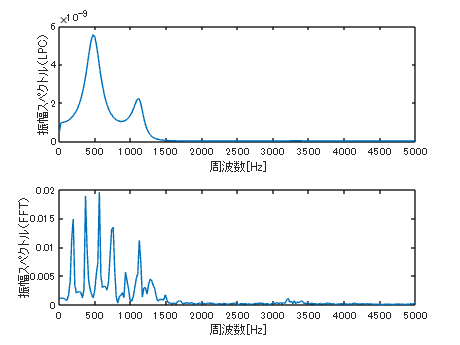

lpcsize = 32;     %LPC次数
fftsize = 2048;   %フーリエ変換の次数, 周波数ポイントの数

[P,f] = pburg(wavdata, lpcsize, fftsize, Fs);  %LPC分析
AP = abs(P) / fftsize;                           %振幅スペクトル

%プロット
fscale = linspace(0, Fs, fftsize);    %0～Fsまでをfftsize個に分割
subplot(2,1,1); plot(fscale(1:fftsize/2), AP(1:fftsize/2)); 
xlabel('周波数[Hz]'); ylabel('振幅スペクトル（LPC）'); xlim([0,5000]);

dft = fft(wavdata, fftsize);                     %比較用のフーリエ変換
Adft = abs(dft) / fftsize;                       %振幅スペクトル
subplot(2,1,2); plot(fscale(1:fftsize/2), Adft(1:fftsize/2)); 
xlabel('周波数[Hz]'); ylabel('振幅スペクトル（FFT）'); xlim([0,5000]);

Peak picking using Yule-Walker method ([`pburg`](https://jp.mathworks.com/help/signal/ref/pburg.html) | [`pcov`](https://jp.mathworks.com/help/signal/ref/pcov.html) | [`pmcov`](https://jp.mathworks.com/help/signal/ref/pmcov.html)`)`

[formant, formantFreq] = findpeaks(AP);
f(formantFreq(1:3))

ans = 1.0e+03 *

    0.4737
    1.0982
    3.3161


formant(1:3)

ans = 1.0e-08 *

    0.5554
    0.2209
    0.0022
